## Synthesis of Robust and stable controler from Desired response 

## Initizilation

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);



## Filter

The controller is designed with only Wref, Wu =0 

s=tf('s');
%Wz feedthrough filter
WZ = 1;
param = model.calculateWz(param,WZ,1);
%Ww lowpass filter 
WW = 2*pi*eye(4)*1/(s+2*pi);
param = model.calculateWw(param,WW,0);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(200*s+1))

wref =
 
  From input 1 to output...
           1
   1:  ---------
       200 s + 1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
           1
   2:  ---------
       200 s + 1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
           1
   3:  ---------
       200 s + 1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
           1
   4:  ---------
       200 s + 1
 
Continuous-time transfer function.


wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
figure()
step(wref(1,1))

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);


## Control

param = control.DesignProcedureRobustPerformanceAndRobustStabilityWeighted(param,1); 

Linear matrix variable 4x28 (full, real, 112 variables)
Coefficient range: 1 to 1


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0320
       solvertime: 0.1846
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|           0.55972|      2.8687e-10|
|   #2|        Matrix inequality|          0.039144|      3.8028e-12|
|   #3|        Matrix inequality|       -5.4226e-17|      1.6503e-11|
|   #4|   Elementwise inequality|            0.2295|      1.6909e-08|
|   #5|        Matrix inequality|          0.020938|      3.7447e-12|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = NaN

gamma desired per


ans = 0.2295

gamma robust stab


ans = NaN

y_out =     2.3484   -0.4199    0.6293         0         0         0         0         0         0         0         0         0    1.2142   -1.1387   -2.0432    0.9256   -0.0000   -0.0000    0.0000    0.0000   -0.0389   -0.0032   -0.0093    0.0049    0.0000    0.0000    0.0000    0.0000
         0         0         0    1.9638   -0.1273    0.1460         0         0         0         0         0         0   -0.2809    0.6621   -1.9024    0.7716    0.0000    0.0000    0.0000    0.0000    0.0005   -0.0068   -0.0069    0.0031    0.0000   -0.0000   -0.0000    0.0000
         0         0         0         0         0         0    1.7170   -0.1736    2.6770         0         0         0   -0.1624   -0.3202    5.3189   -0.5270   -0.0000   -0.0000   -0.0000    0.0000   -0.0005   -0.0013   -0.1679   -0.0019   -0.0000    0.0000    0.0000   -0.0000
         0         0         0         0         0         0         0         0         0    1.8527   -0.2345    0.0447   -0.0510    0.1771   -2.400

k =    15.7884    0.5729    0.1294         0         0         0         0         0         0         0         0         0
         0         0         0   35.7087    0.9455    0.3113         0         0         0         0         0         0
         0         0         0         0         0         0   44.3483    0.8334    0.3930         0         0         0
         0         0         0         0         0         0         0         0         0   42.2217    0.9069    0.3730


Eig of Q_hat


ans = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0004
    0.0014
    0.0014


## Simulate the linear response

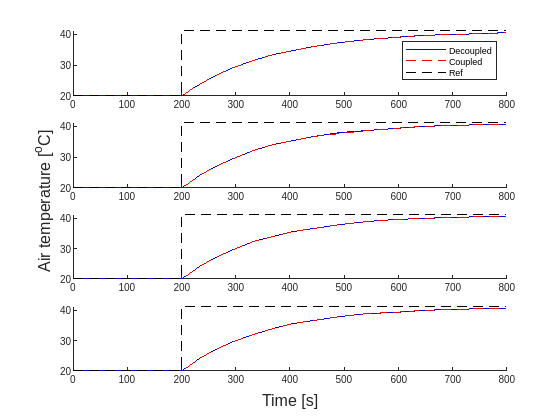

ans = struct with fields:
    time: [52×1 double]
      Tw: [52×4 double]
      Ta: [52×4 double]
       T: [52×4 double]


util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref",0,800,21)

## Correcting the response by applying a fitted desired response 

## Filter

The controller is designed with only Wref, where Wref have been fitted to give the desired response, and  Wu =0 

s=tf('s');
%Wz feedthrough filter
WZ = 1;
param = model.calculateWz(param,WZ,1);
%Ww lowpass filter 
WW = 2*pi*eye(4)*1/(s+2*pi);
param = model.calculateWw(param,WW,0);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(200*s+1))

wref =
 
  From input 1 to output...
           1
   1:  ---------
       200 s + 1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
           1
   2:  ---------
       200 s + 1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
           1
   3:  ---------
       200 s + 1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
           1
   4:  ---------
       200 s + 1
 
Continuous-time transfer function.


wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
figure()
step(wref(1,1))

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);


## Control

param = control.DesignProcedureRobustPerformanceAndRobustStabilityWeighted(param,1); 

Linear matrix variable 4x28 (full, real, 112 variables)
Coefficient range: 1 to 1


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0313
       solvertime: 0.1827
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|           0.55972|      2.8687e-10|
|   #2|        Matrix inequality|          0.039144|      3.8028e-12|
|   #3|        Matrix inequality|       -5.4226e-17|      1.6503e-11|
|   #4|   Elementwise inequality|            0.2295|      1.6909e-08|
|   #5|        Matrix inequality|          0.020938|      3.7447e-12|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = NaN

gamma desired per


ans = 0.2295

gamma robust stab


ans = NaN

y_out =     2.3484   -0.4199    0.6293         0         0         0         0         0         0         0         0         0    1.2142   -1.1387   -2.0432    0.9256   -0.0000   -0.0000    0.0000    0.0000   -0.0389   -0.0032   -0.0093    0.0049    0.0000    0.0000    0.0000    0.0000
         0         0         0    1.9638   -0.1273    0.1460         0         0         0         0         0         0   -0.2809    0.6621   -1.9024    0.7716    0.0000    0.0000    0.0000    0.0000    0.0005   -0.0068   -0.0069    0.0031    0.0000   -0.0000   -0.0000    0.0000
         0         0         0         0         0         0    1.7170   -0.1736    2.6770         0         0         0   -0.1624   -0.3202    5.3189   -0.5270   -0.0000   -0.0000   -0.0000    0.0000   -0.0005   -0.0013   -0.1679   -0.0019   -0.0000    0.0000    0.0000   -0.0000
         0         0         0         0         0         0         0         0         0    1.8527   -0.2345    0.0447   -0.0510    0.1771   -2.400

k =    15.7884    0.5729    0.1294         0         0         0         0         0         0         0         0         0
         0         0         0   35.7087    0.9455    0.3113         0         0         0         0         0         0
         0         0         0         0         0         0   44.3483    0.8334    0.3930         0         0         0
         0         0         0         0         0         0         0         0         0   42.2217    0.9069    0.3730


Eig of Q_hat


ans = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0004
    0.0014
    0.0014


## Simulate the linear response

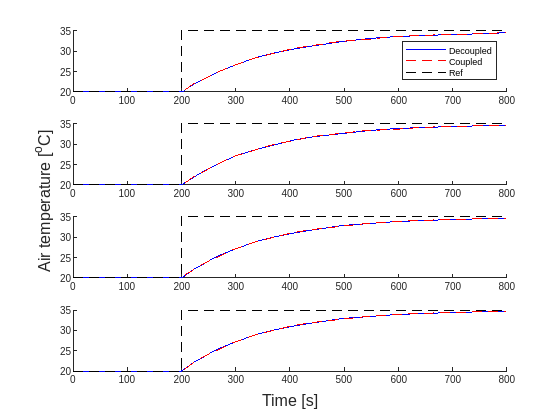


[decoupleResult, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref_fitted_30",0,800,15);

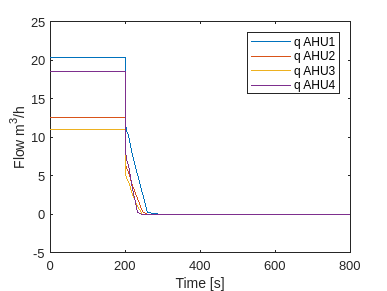

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowIncreaseTempBy10Deg","epsc")

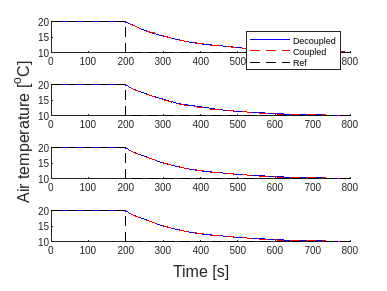

[decoupleResult, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref_fitted_10",0,800,-10);

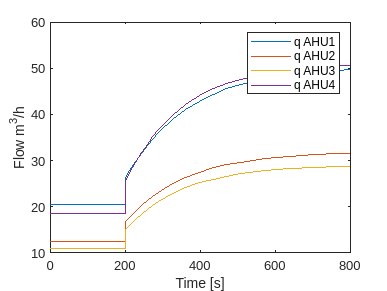

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
% yline(param.ctrl.q_OP,"--b")
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowLowerTempBy10Deg","epsc")

## Verify robust stability

By calculating Mw and taking the Hinfnorm the robust stability can be verified 

Mw = model.calculateMw(param);
hinfnorm(Mw)

ans = 0.2282